# mAD merge

## IO

% sample = '8months_disease-ADmouse_9723_2'
% sample = '8months_control-ADmouse_9707'
% sample = '13months_disease-ADmouse_11346'
% sample = '13months_control-ADmouse_11351'

sample = '13months_control-ADmouse_11351'


base_path = 'Z:/Data/Processed/2022-01-03-Hu-AD_3_samples_Rep/'

base_path = 'Z:/Data/Processed/2022-01-03-Hu-AD_3_samples_Rep/'

config_path = fullfile('Z:/Data/Analyzed/2022-01-03-Hu-AD/', sample, 'round1_merged/');
seg_path = fullfile('Z:/Data/Analyzed/2022-01-03-Hu-AD/', sample, 'segmentation/');
out_path = fullfile('Z:/Data/Analyzed/2022-01-03-Hu-AD/', sample);

input_path = fullfile(base_path, 'output/max');
input_dim = [3072 3072 30 4];

data_dirs = dir(fullfile(input_path, "Position*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name);

Ndirs = numel(data_dirs);

rotation_degress = -90; 

## Load TileConfiguration from Fiji stitching

% merge dots 
stitch_file = fullfile(config_path, "TileConfiguration.registered.txt");
%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [5, Inf];
opts.Delimiter = ["(", ")", ",", ";"];

% Specify column names and types
opts.VariableNames = ["Definetheimagecoordinates", "Var2", "Var3", "VarName4", "VarName5"];
opts.SelectedVariableNames = ["Definetheimagecoordinates", "VarName4", "VarName5"];
opts.VariableTypes = ["double", "string", "string", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, ["Var2", "Var3"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "Var3"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Definetheimagecoordinates", "TrimNonNumeric", true);
opts = setvaropts(opts, "Definetheimagecoordinates", "ThousandsSeparator", ",");

% Import the data
TileConfiguration = readtable(stitch_file, opts);
TileConfiguration.Properties.VariableNames = {'tile' 'x' 'y'};
TileConfiguration.x = int32(fix(TileConfiguration.x));
TileConfiguration.y = int32(fix(TileConfiguration.y));

head(TileConfiguration, 5)

ans = 5×3 table
    tile      x      y 
    ____    _____    __

      1         0     0
     10      2773     7
     19      5536    14
     28      8306    23
     37     11070    26



%% Clear temporary variables
clear opts

% Global offsets 
offset_x = abs(min(TileConfiguration.x));
offset_y = abs(min(TileConfiguration.y));

TileConfiguration.x = TileConfiguration.x + offset_x + 1;
TileConfiguration.y = TileConfiguration.y + offset_y + 1;

## merge spots

% load stitched dapi image
dapi_file = fullfile(seg_path, 'overlay.tif');
%  dapi_img = imread_big(dapi_file);
dapi_max = imread(dapi_file);
trim_range = (1:30);

merged_points = int32([]);
merged_reads = {};
merged_region = [];

for r=1:size(TileConfiguration,1)
    
    % get each row of tileconfig
    curr_row = table2cell(TileConfiguration(r, :));
    [tile, x, y] = curr_row{:};
    
    % load dots of each tile
    curr_position_dir = sprintf("Position%03d", tile)
    curr_dot_file = fullfile(input_path, curr_position_dir, "goodPoints_max3d.mat");
    load(curr_dot_file);
    
    if ~isempty(tile_goodReads)
         if rotation_degress == -90
            % rotate 90 c
            temp = tile_goodSpots;
            tile_goodSpots(:, 2) = temp(:, 1);
            tile_goodSpots(:, 1) = 3073 - temp(:, 2);
        elseif rotation_degress == -180
            % rotate 180 c
            temp = tile_goodSpots;
            tile_goodSpots(:, 1) = 3073 - temp(:, 1);
            tile_goodSpots(:, 2) = 3073 - temp(:, 2);
        end
        
        % trim along z
        toKeep = ismember(tile_goodSpots(:,3), trim_range);
        tile_goodSpots = tile_goodSpots(toKeep, :);
        tile_goodReads = tile_goodReads(toKeep);

        tile_goodSpots = int32(tile_goodSpots) + int32([x y 0]);
            
        % construct dots region
        current_min = min(tile_goodSpots, [], 1);
        current_max = max(tile_goodSpots, [], 1);
        if current_max(1) > size(dapi_max, 2)
            fprintf("1")
            current_max(1) = size(dapi_max, 2);
            toKeep = tile_goodSpots(:, 1) <= current_max(1);
            tile_goodSpots = tile_goodSpots(toKeep, :);
            tile_goodReads = tile_goodReads(toKeep);
        
        else if current_max(2) > size(dapi_max, 1)
                fprintf("2")
                current_max(2) = size(dapi_max, 1);   
             
                toKeep = tile_goodSpots(:, 2) <= current_max(2);
                tile_goodSpots = tile_goodSpots(toKeep, :);
                tile_goodReads = tile_goodReads(toKeep);
            
        end
        end
        current_region = zeros(size(dapi_max));
        current_region(current_min(2):current_max(2), current_min(1):current_max(1)) = 1;
        
        % merge dots 
        if isempty(merged_region)
            merged_region = current_region;
        else
            current_overlap = merged_region & current_region;
            merged_region = merged_region | current_region;
            current_region = current_region - current_overlap; 
            
            temp_cell = num2cell(tile_goodSpots, 2); 
            current_lindex = cellfun(@(x) sub2ind([size(dapi_max) input_dim(3)], x(2), x(1)), temp_cell);
            current_logical = logical(current_region(current_lindex));
            tile_goodSpots = tile_goodSpots(current_logical, :);
            tile_goodReads = tile_goodReads(current_logical);
        end
        
        % save current 
        merged_points = [merged_points; tile_goodSpots];
        merged_reads = [merged_reads; tile_goodReads];
    end
end

curr_position_dir = "Position001"

curr_position_dir = "Position010"

curr_position_dir = "Position019"

curr_position_dir = "Position028"

curr_position_dir = "Position037"

curr_position_dir = "Position046"

curr_position_dir = "Position055"

curr_position_dir = "Position002"

curr_position_dir = "Position011"

curr_position_dir = "Position020"

curr_position_dir = "Position029"

curr_position_dir = "Position038"

curr_position_dir = "Position047"

curr_position_dir = "Position056"

curr_position_dir = "Position003"

curr_position_dir = "Position012"

curr_position_dir = "Position021"

curr_position_dir = "Position030"

curr_position_dir = "Position039"

curr_position_dir = "Position048"

curr_position_dir = "Position057"

curr_position_dir = "Position004"

curr_position_dir = "Position013"

curr_position_dir = "Position022"

curr_position_dir = "Position031"

curr_position_dir = "Position040"

curr_position_dir = "Position049"

curr_position_dir = "Position058"

curr_position_dir = "Position005"

curr_position_dir = "Position014"

curr_position_dir = "Position023"

curr_position_dir = "Position032"

curr_position_dir = "Position041"

curr_position_dir = "Position050"

curr_position_dir = "Position059"

curr_position_dir = "Position006"

curr_position_dir = "Position015"

curr_position_dir = "Position024"

curr_position_dir = "Position033"

curr_position_dir = "Position042"

curr_position_dir = "Position051"

curr_position_dir = "Position060"

curr_position_dir = "Position007"

curr_position_dir = "Position016"

curr_position_dir = "Position025"

curr_position_dir = "Position034"

curr_position_dir = "Position043"

curr_position_dir = "Position052"

curr_position_dir = "Position061"

curr_position_dir = "Position008"

curr_position_dir = "Position017"

curr_position_dir = "Position026"

curr_position_dir = "Position035"

curr_position_dir = "Position044"

curr_position_dir = "Position053"

curr_position_dir = "Position062"

curr_position_dir = "Position009"

curr_position_dir = "Position018"

curr_position_dir = "Position027"

curr_position_dir = "Position036"

curr_position_dir = "Position045"

curr_position_dir = "Position054"

curr_position_dir = "Position063"

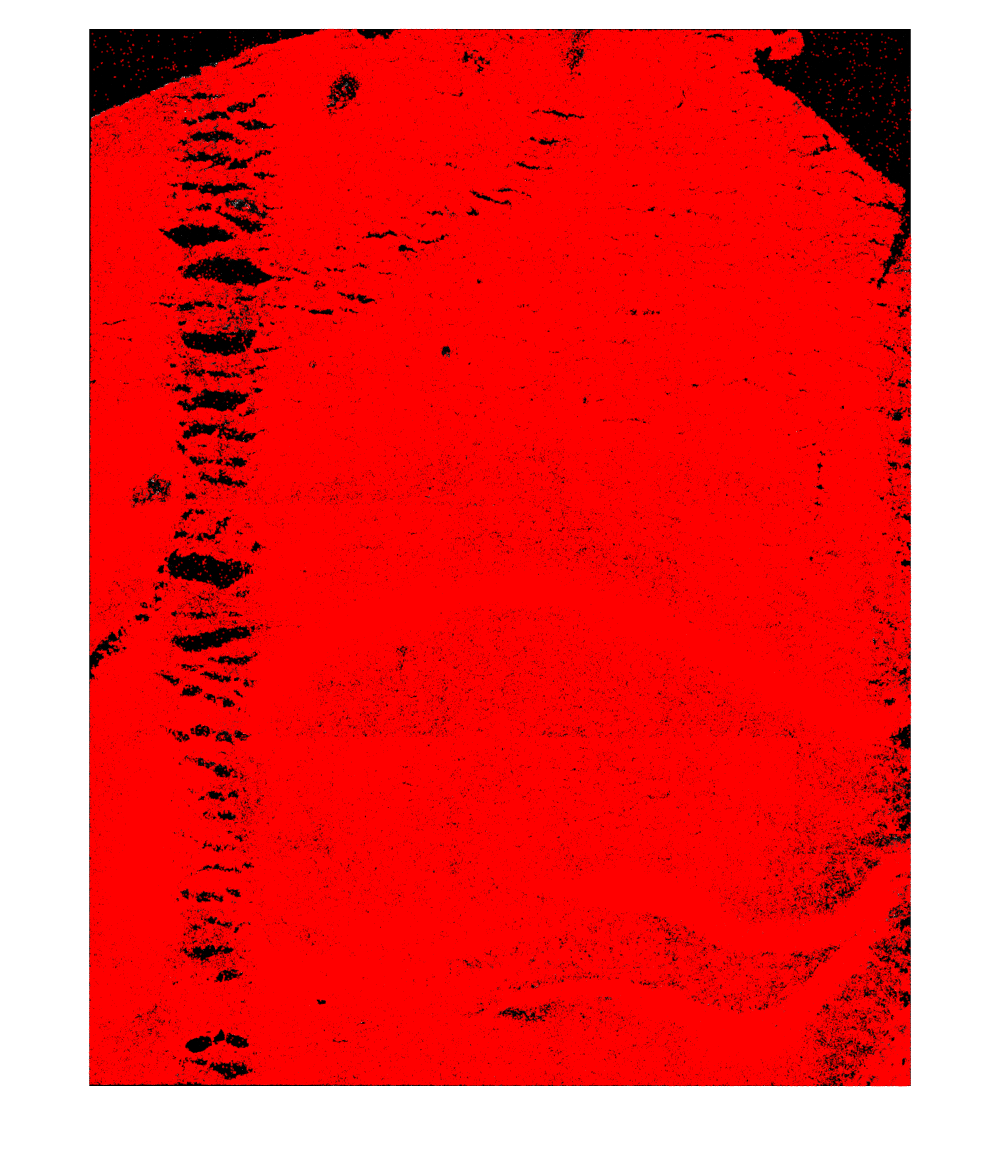


plot_centroids(merged_points, dapi_max, 1)


save(fullfile(out_path, 'merged_goodPoints_max3d.mat'), "merged_points", "merged_reads");